% load the module data for 120 reps on R = 5, earlyStop = 60
% if it is of the full length, we need to set earlyStop = 100 with
% moduleResultfull.mat
clear; close all;
epochEarlystop = 100;

for i = 1:120
    i
    folderName_R_5_rep_120_diff_data{i} = sprintf('r_5_rep_120_diff_data/%d',i);
    dataFile_R_5_rep_120_diff_data{i} = load(sprintf('data/%s/moduleResultFull.mat',folderName_R_5_rep_120_diff_data{i}));
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

% examine the two types of learning curve separately
% plot Type I: warm-up-then-increase
load("accuTypeMannual.mat");
type_1_flex_stack = [];
type_1_acc_stack = [];
type_1_modu_stack = [];
type_1_eta_stack = [];
type_1_stationarity_stack = [];
type_1_nCommunity_stack = [];

type_2_flex_stack = [];
type_2_acc_stack = [];
type_2_modu_stack = [];
type_2_eta_stack = [];
type_2_stationarity_stack = [];
type_2_nCommunity_stack = [];


for i = 1:120
    if accCurveType(i) == 1
        type_1_flex_stack = cat(2,type_1_flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
        type_1_acc_stack = cat(2, type_1_acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
        type_1_modu_stack = cat(2, type_1_modu_stack, dataFile_R_5_rep_120_diff_data{i}.modularity(1:epochEarlystop));
        type_1_eta_stack = cat(2,type_1_eta_stack, dataFile_R_5_rep_120_diff_data{i}.eta(1:epochEarlystop));
        type_1_stationarity_stack = cat(2, type_1_stationarity_stack, dataFile_R_5_rep_120_diff_data{i}.stationarity(1:epochEarlystop));
        type_1_nCommunity_stack = cat(2, type_1_nCommunity_stack, dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop));
        
    end
    if accCurveType(i) == 2
        type_2_flex_stack = cat(2,type_2_flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
        type_2_acc_stack = cat(2, type_2_acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
        type_2_modu_stack = cat(2, type_2_modu_stack, dataFile_R_5_rep_120_diff_data{i}.modularity(1:epochEarlystop));
        type_2_eta_stack = cat(2,type_2_eta_stack, dataFile_R_5_rep_120_diff_data{i}.eta(1:epochEarlystop));
        type_2_stationarity_stack = cat(2, type_2_stationarity_stack, dataFile_R_5_rep_120_diff_data{i}.stationarity(1:epochEarlystop));
        type_2_nCommunity_stack = cat(2, type_2_nCommunity_stack, dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop));
    end
end



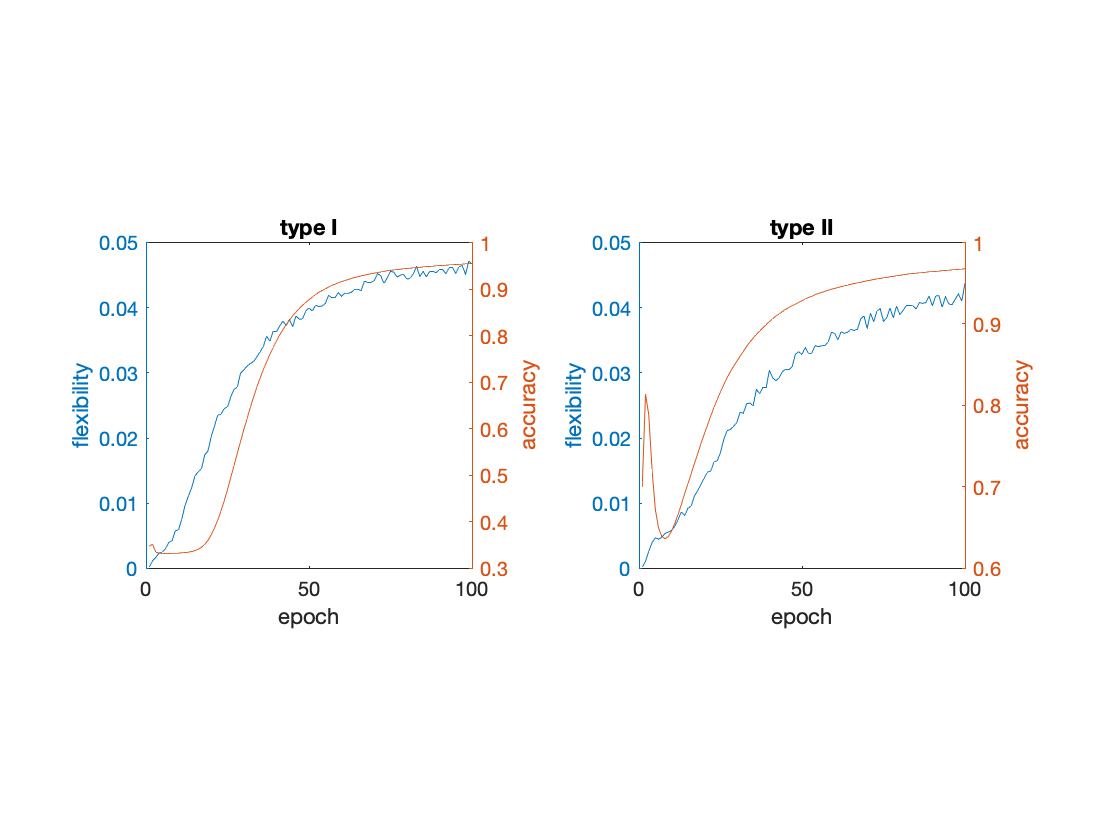


figure;
% plot flexibility & accuracy
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_flex_stack,2));
ylabel('flexibility')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_flex_stack,2));
ylabel('flexibility')
yyaxis right;
plot(mean(type_2_acc_stack,2));
ylabel('accuracy')
title('type II');
xlabel('epoch');
axis square;

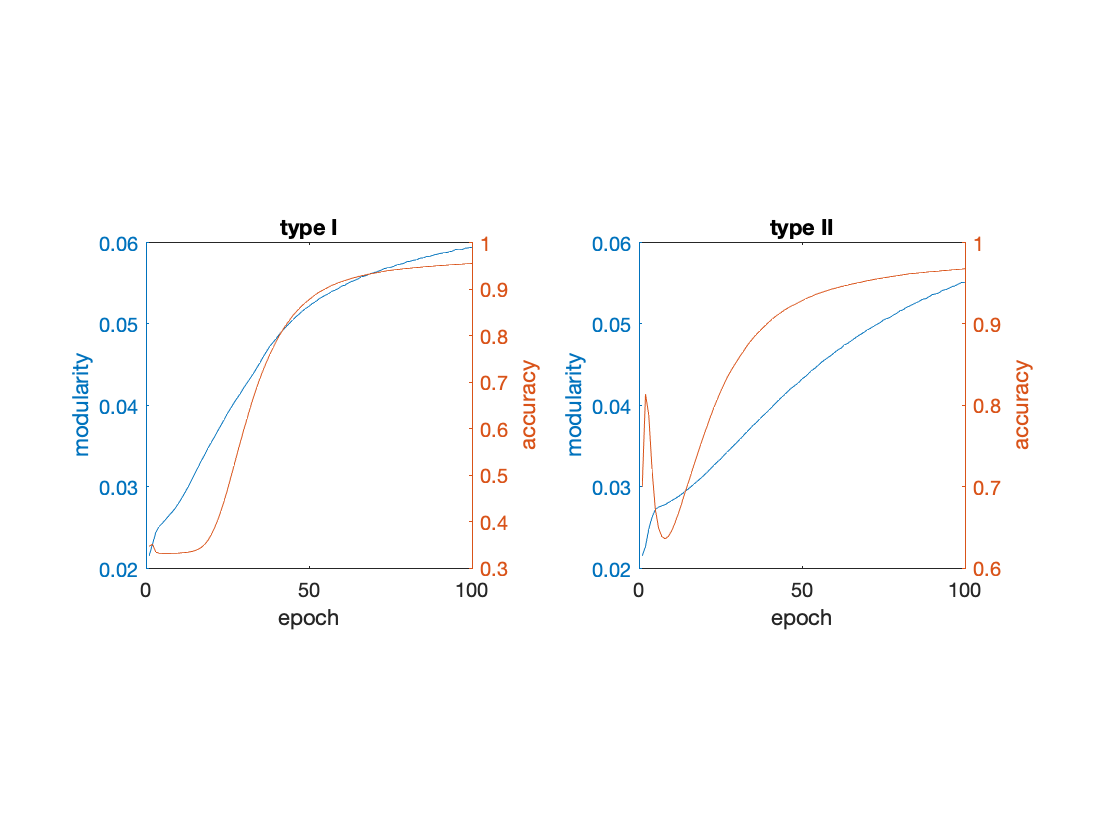


figure;
% plot modularity & accuracy
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_2_acc_stack,2));
ylabel('accuracy')
title('type II');
xlabel('epoch');
axis square;

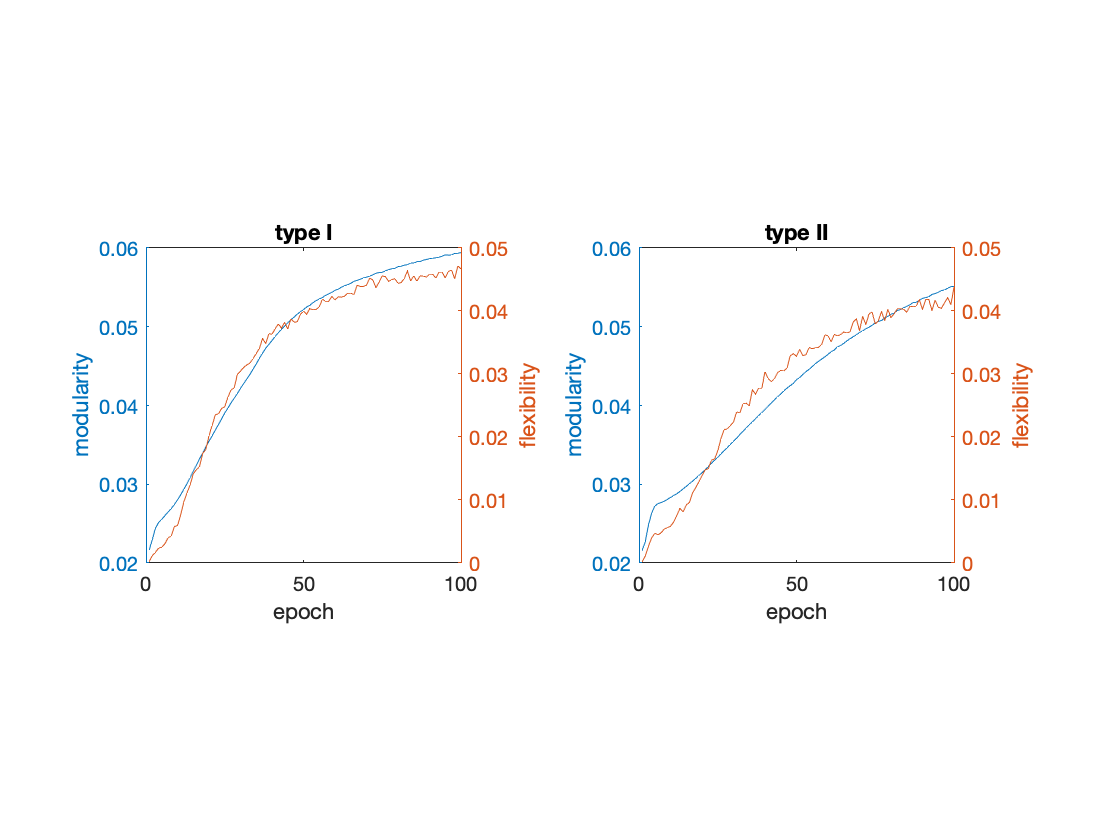


figure;
% plot modularity & flexibility
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_1_flex_stack,2));
ylabel('flexibility')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_2_flex_stack,2));
ylabel('flexibility')
title('type II');
xlabel('epoch');
axis square;

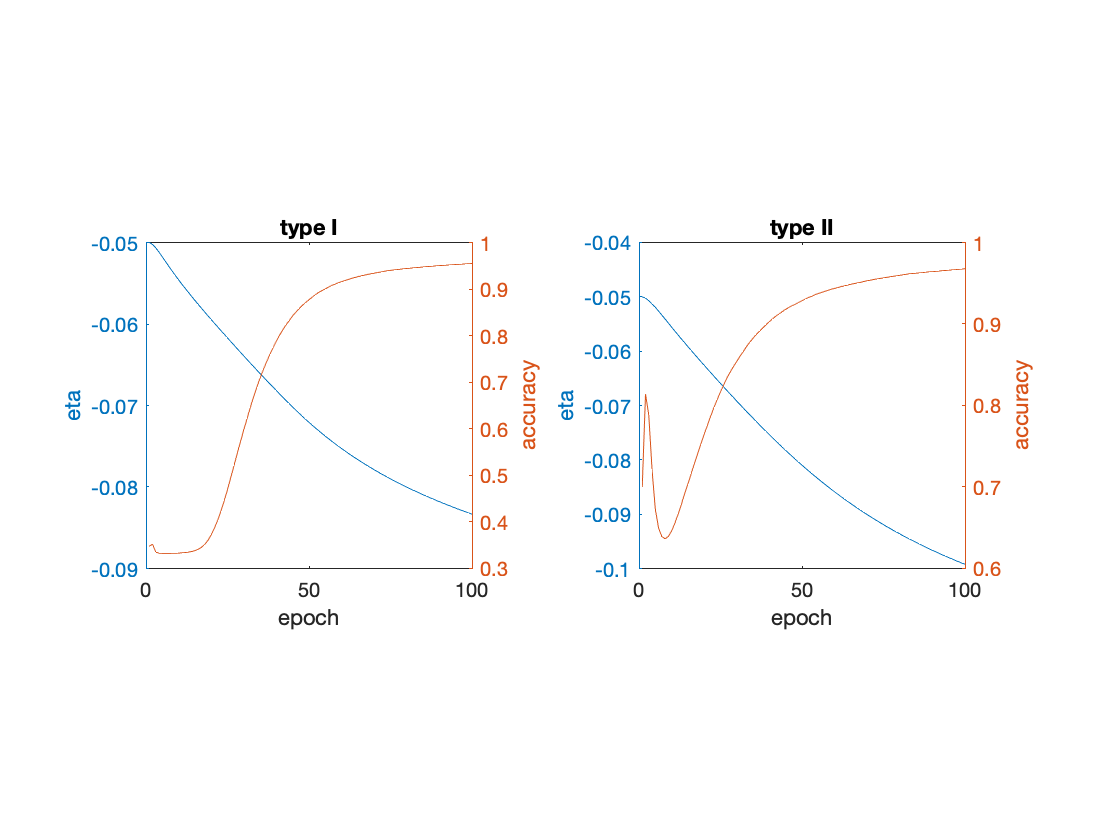



% type_1_eta_stack = [];
% type_1_stationarity_stack = [];
% type_1_nCommunity_stack = [];
figure;
% plot eta & accuracy
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_eta_stack,2));
ylabel('eta')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_eta_stack,2));
ylabel('eta')
yyaxis right;
plot(mean(type_2_acc_stack,2));
ylabel('accuracy')
title('type II');
xlabel('epoch');
axis square;

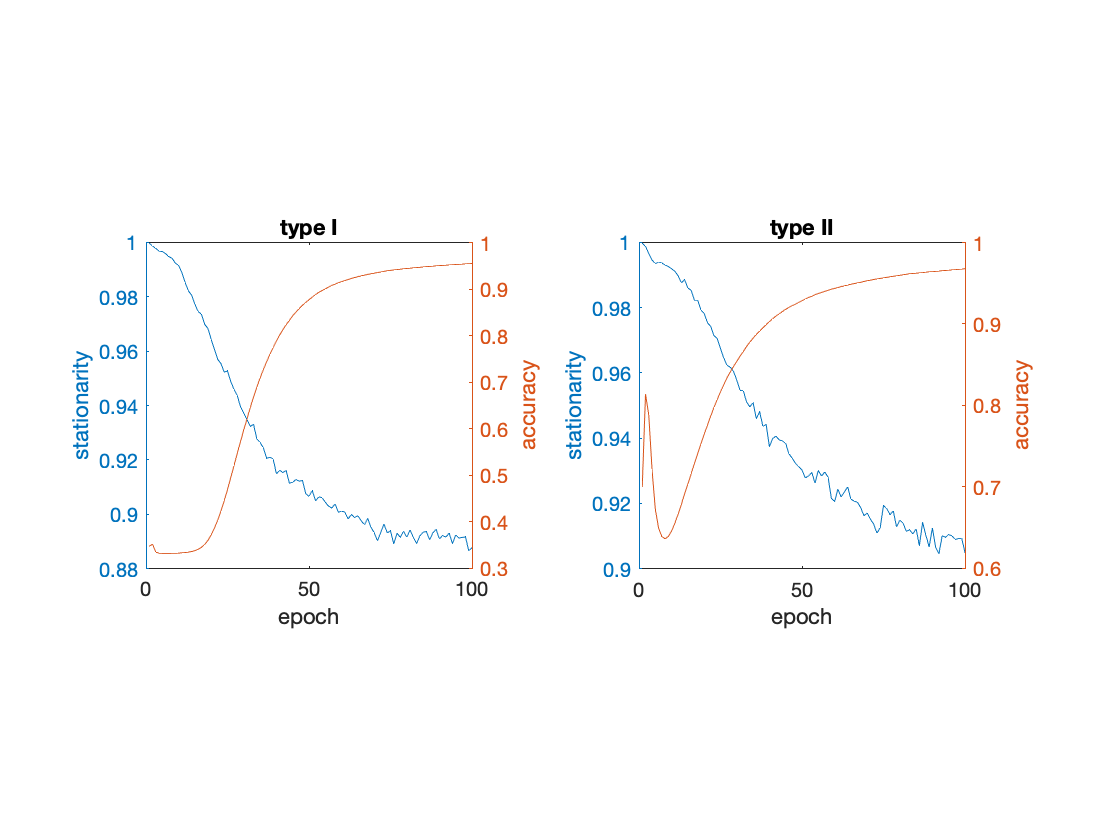


figure;
% plot stationarity & accuracy
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_stationarity_stack,2));
ylabel('stationarity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_stationarity_stack,2));
ylabel('stationarity')
yyaxis right;
plot(mean(type_2_acc_stack,2));
ylabel('accuracy')
title('type II');
xlabel('epoch');
axis square;

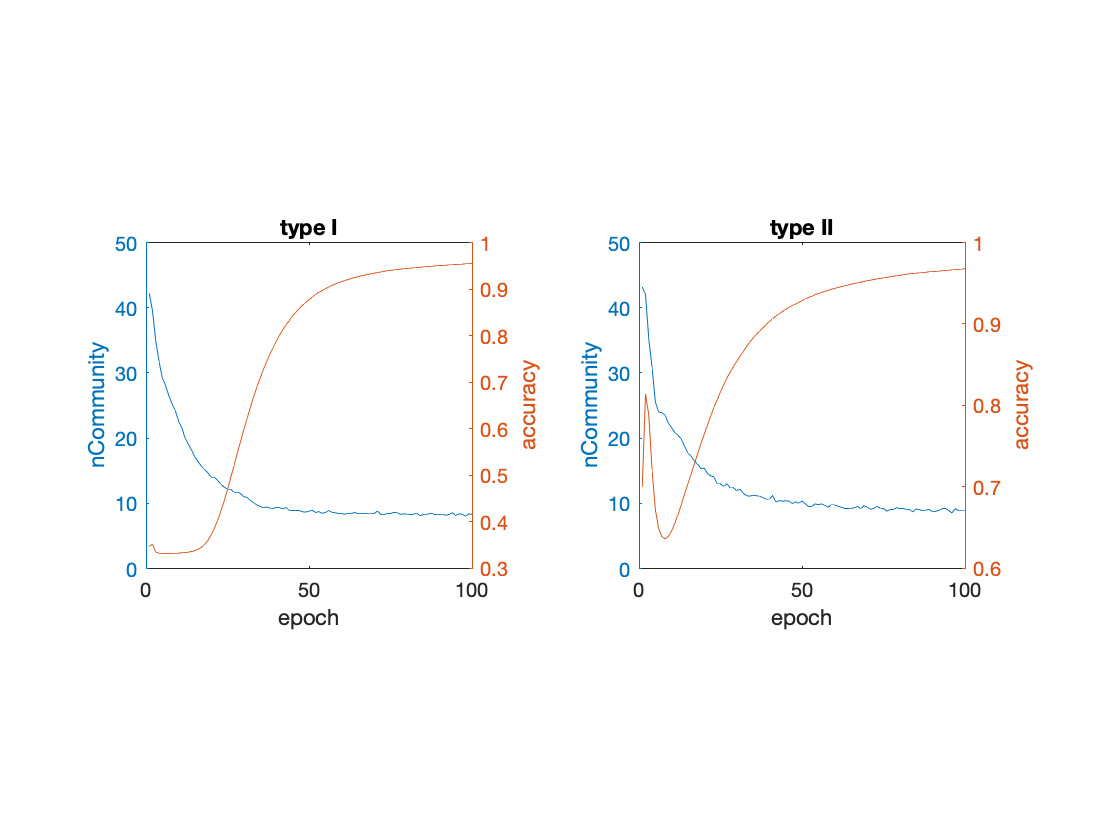



figure;
% plot nCommunity & accuracy
subplot(1,2,1)
yyaxis left;
plot(mean(type_1_nCommunity_stack,2));
ylabel('nCommunity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

subplot(1,2,2)
yyaxis left;
plot(mean(type_2_nCommunity_stack,2));
ylabel('nCommunity')
yyaxis right;
plot(mean(type_2_acc_stack,2));
ylabel('accuracy')
title('type II');
xlabel('epoch');
axis square;

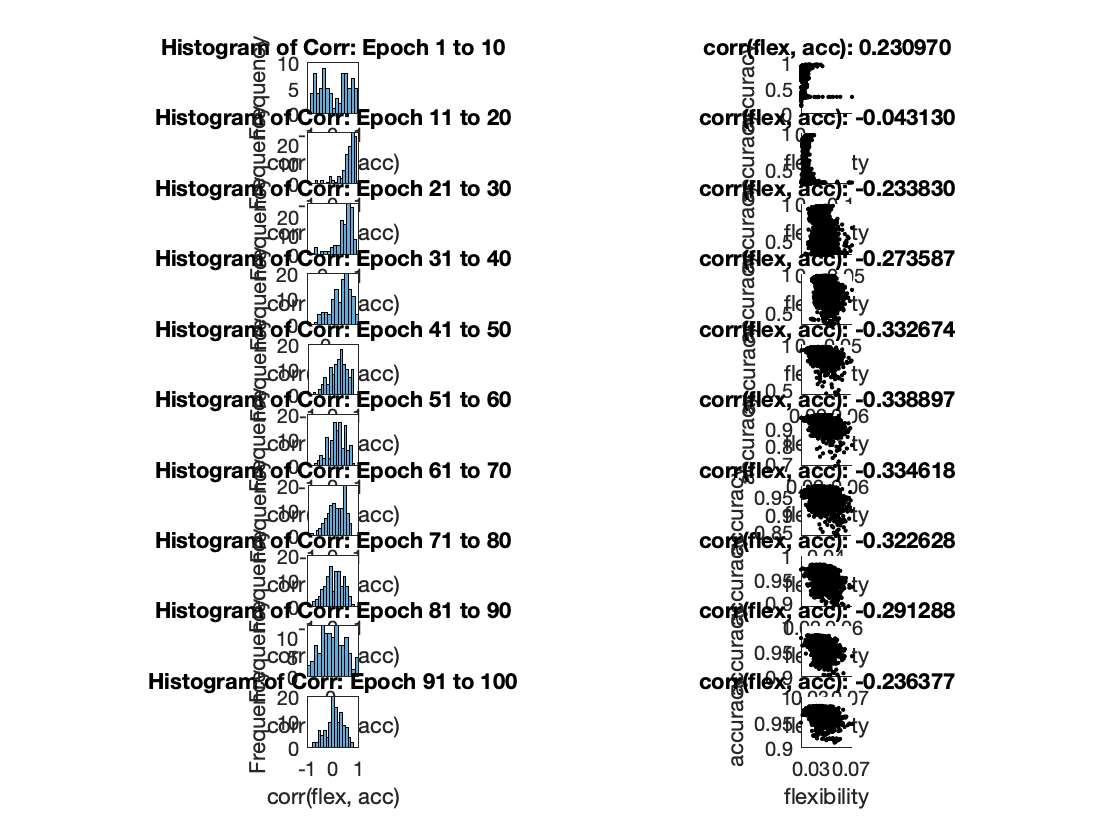


% visualize the degree distribution for individual difference and within subjects
% visualize the relationship between accuracy and flexibility separately
epochDiff = 10;
nEpochWinSize = epochEarlystop / epochDiff;

flex_acc_pair = cell(nEpochWinSize,1);
flex_acc_corr = zeros(120,nEpochWinSize);

for k = 1:length(flex_acc_pair)
    flex_acc_pair{k} = [0,0];
    epochStart = 1 + epochDiff*(k-1);
    epochEnd= epochDiff*k;
    for i = 1:120
        flex_acc_pair{k} = cat(1, flex_acc_pair{k},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
        flex_acc_corr(i,k) = corr(dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd), dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd));
    end
    flex_acc_pair{k} = flex_acc_pair{k}(2:end,:);
end
figure;
colNum = nEpochWinSize/2;
for i = 1:nEpochWinSize
    subplot(nEpochWinSize,2,2*i-1);
    histogram(flex_acc_corr(:,i),15);
    axis square;
    title(sprintf('Histogram of Corr: Epoch %d to %d', 1 + epochDiff*(i-1), epochDiff*i));
    xlabel('corr(flex, acc)');
    ylabel('Frequency');
end
for i = 1:nEpochWinSize
    subplot(nEpochWinSize,2,2*i);
    scatter(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2),'black', '.'); hold on;
    axis square;
    title(sprintf('corr(flex, acc): %f', corr(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2))));
    xlabel('flexibility');
    ylabel('accuracy');
end

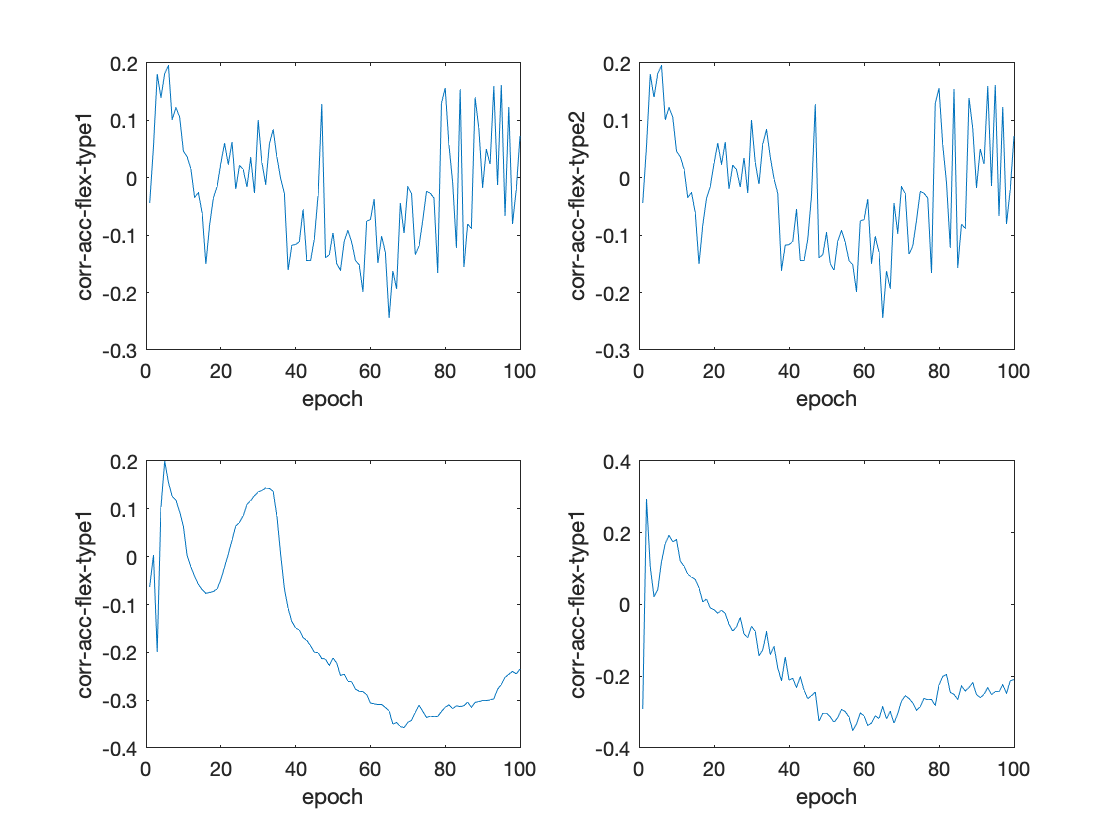

% visualize the correlation within the epoch across Time and Subjects in
% two types
% visualize for Type I
corr_acc_flex_type1 = zeros(epochEarlystop,1);
corr_acc_flex_type2 = zeros(epochEarlystop,1);
corr_acc_modu_type1 = zeros(epochEarlystop,1);
corr_acc_modu_type2 = zeros(epochEarlystop,1);
for i  = 1:epochEarlystop
    corr_acc_flex_type1(i) = corr(type_1_acc_stack(i,:)', type_1_flex_stack(i,:)');
    corr_acc_flex_type2(i) = corr(type_2_acc_stack(i,:)', type_2_flex_stack(i,:)');
    corr_acc_modu_type1(i) = corr(type_1_acc_stack(i,:)', type_1_modu_stack(i,:)');
    corr_acc_modu_type2(i) = corr(type_2_acc_stack(i,:)', type_2_modu_stack(i,:)');
end

figure;
subplot(2,2,1);
plot(corr_acc_flex_type1);
xlabel('epoch');
ylabel('corr-acc-flex-type1');

subplot(2,2,2);
plot(corr_acc_flex_type1);
xlabel('epoch');
ylabel('corr-acc-flex-type2');

subplot(2,2,3);
plot(corr_acc_modu_type1);
xlabel('epoch');
ylabel('corr-acc-flex-type1');

subplot(2,2,4);
plot(corr_acc_modu_type2);
xlabel('epoch');
ylabel('corr-acc-flex-type1');

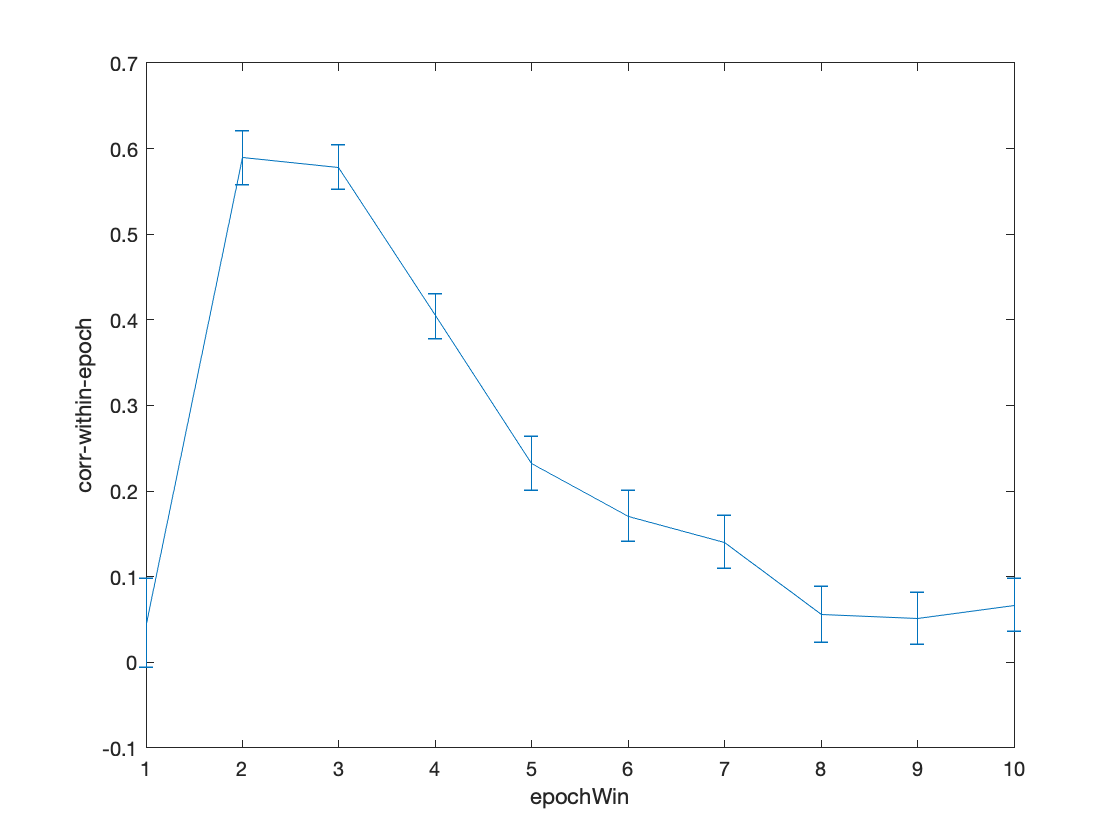


figure;
errorbar(nanmean(flex_acc_corr),nanstd(flex_acc_corr)/sqrt(120));
xlabel('epochWin');
ylabel('corr-within-epoch');